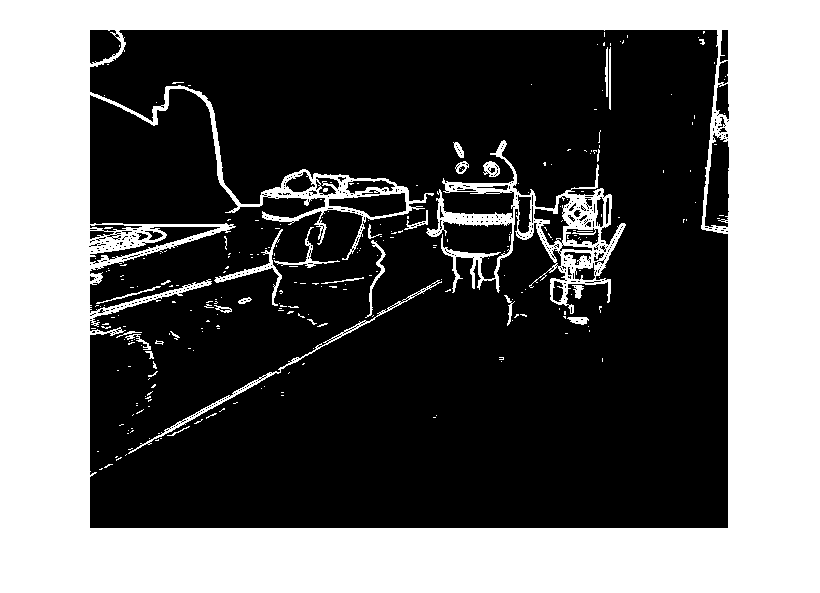

%Añadimos el path donde se encuentra la imagen 

addpath("G:\Mi unidad\MCC\Primer Semestre\Visión Computacional\Codigos Vision\GitRepository\Vision-Computacional\Bordes + SIFT");
addpath("G:\Mi unidad\MCC\Primer Semestre\Visión Computacional\Codigos Vision\GitRepository\Vision-Computacional\Bordes + SIFT\Explicación del codigo")
addpath("G:\Mi unidad\MCC\Primer Semestre\Visión Computacional\Codigos Vision\GitRepository\Vision-Computacional\Bordes + SIFT\Filtrado")
img = im2double(imread('im.jpg'));

%Creamos nuestro detector de bordes bastante sencillo
edgeDetector  = EdgeDetector(GradientMethods.SOBEL,0.08);
%Obtenemos los bordes de la imagen 
borders = edgeDetector.computeEdges(img);

figure()
imshow(borders)

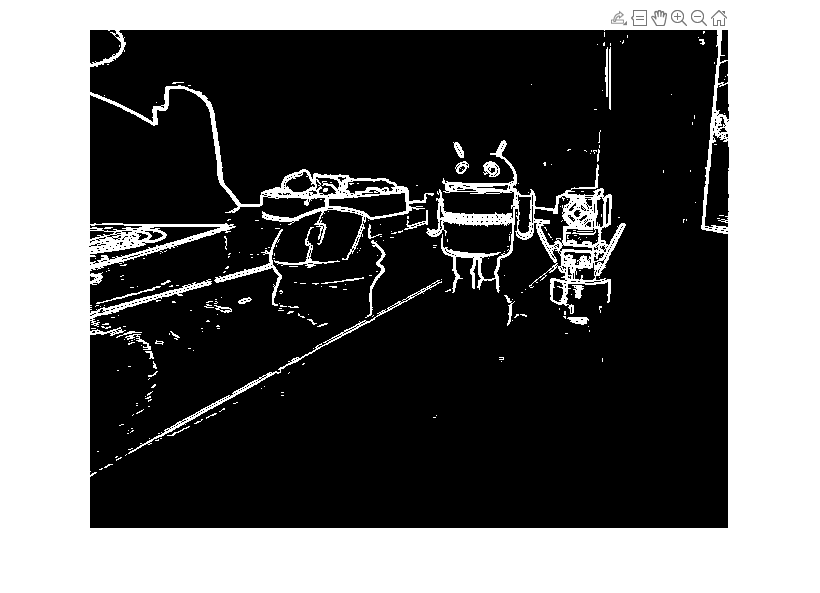

%Ahora quisiera aislar el monito de android
cropped =double(imcrop(borders));

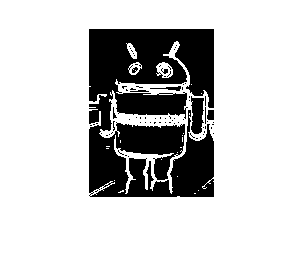

cropped = cropped/255;
figure()
imshow(cropped)

imwrite(cropped,'imnormal.png');

% Bien ahora, lo que hare será obtener el invariante 
invCalc = MomentInvariantCalculator();
mom = invCalc.obtainArticleInvariant(cropped);
huMom = invCalc.obtainHuMoments(cropped);

   65.0769

   89.6718



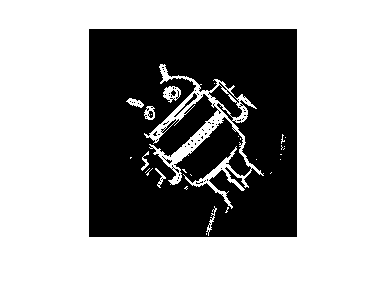

%Ahora vamos a rotar la imagen 
rotatedImg = imrotate(cropped,45); 
imwrite(rotatedImg,'imrot.png')
figure()
imshow(rotatedImg)

%Obtenemos el invariante
momRot = invCalc.obtainArticleInvariant(rotatedImg);
huMomRot = invCalc.obtainHuMoments(rotatedImg);

  109.6586

  106.8808



imshow(rot90(cropped))